% Exercise 2


len = 50;
x = rand(1,len);
y = x + randn(1,len);

% Splitting data
n = length(x);
k = 2;                  % how many parts to use
allix = randperm(n);    % all data indices, randomly ordered
numineach = ceil(n/k);  % at least one part must have this many data points
% Indexes for each of parts
allix = reshape([allix NaN(1,k*numineach-n)],k,numineach);

% Train half
train_x = x(allix(1,:));
train_y = y(allix(1,:));
% Test half
test_x = x(allix(2,:));
test_y = y(allix(2,:));

% Perform linear regression
X = [train_x' ones(length(train_x),1)];
h = inv(X'*X)*X' * train_y';

% Fitted model on the first half of data
modelfit_train = X *h;

% Calculate R2 for the fitted model and actual training data
train_r2 = computeR2(train_y, modelfit_train');

% Fitted model on the second half of data
modelfit_test = [test_x' ones(length(test_x),1)] * h;

% Calculate R2 for the fit model and test data
test_r2 = computeR2(test_y, modelfit_test');


% The R2 between train part  and test part is quite diffirent in case of a
% a low size of sample. For example, in case, where n > 1000, the R2
% metric for both train and test part approximately the same, that means
% the model is pretty accurate.

% We can say that the model is unrelaible regarding that n = 50.

fprintf('R2 between the train data and fitted model: %.2f%%',train_r2);

R2 between the train data and fitted model: 16.48%

fprintf('R2 between the test data and fitted model: %.2f%%',test_r2);

R2 between the test data and fitted model: 7.85%

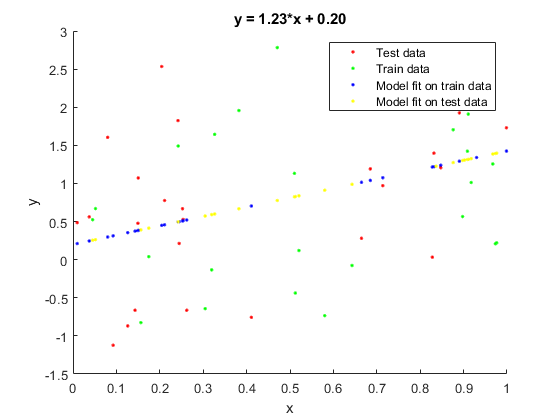


% visualize
figure;
hold on;
%a = scatter(x,y,'k.');
a_1 = plot(train_x,train_y,'r.');
a_2 = plot(test_x,test_y,'g.');
b = scatter(train_x,modelfit_train,'b.');
c = scatter(test_x,modelfit_test,'y.');
xlabel('x');
ylabel('y');
legend([a_1 a_2 b c], 'Test data','Train data', 'Model fit on train data', 'Model fit on test data')
title(sprintf('y = %.2f*x + %.2f',h(1),h(2)));

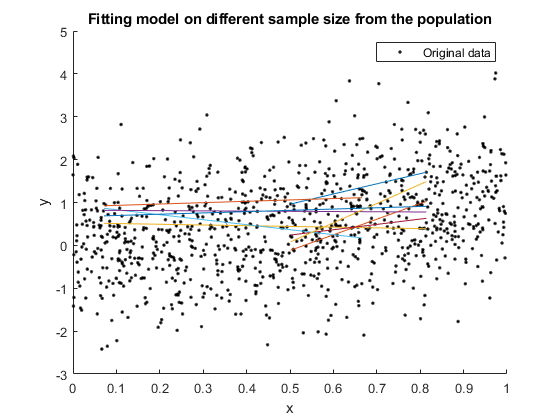

% Exercise 3.

x = rand(1,1000);
y = x+randn(1,1000);

% Sample size
n = 5;

% bootstrapping size 
numboots = 10;

% perform the bootstraps
x_samples = zeros(numboots, n);
modelfit = zeros(numboots, n);
params = zeros(numboots, 2);

for boot=1:numboots
    
    % prepare data indices
    % rand(1,n) = [0:1](1x100)
    ix = ceil(n*rand(1,n));
    
    x_samples(boot,:) = x(ix);
    
    % construct regressor matrix
    X = [x(ix)' ones(n,1)];
    
    % edstimate parameters
    h = inv(X' * X) * X'*y(ix)';
    
    % evaluate the model
    modelfit(boot,:) = x(ix)*h(1) + h(2);
    
    % record the parameters
    params(boot,:) = h;
end

% visualize
figure;
hold on;
xlabel('x');
ylabel('y');
title('Fitting model on different sample size from the population')


% First, plot our dots
h1 = scatter(x,y,'.k');

% Then draw the lines  for the models fitted on diffirent samples
X = [x(ix)' ones(n,1)];
modelfit_fit  = X * h;

% Plot them all
h2 = plot(x_samples', modelfit');
uistack(h2,'top')

legend([h1], 'Original data')


% Summary: the lower size of a sample, the less accurate the fitted model.
% For better stability, it requires to use a larger sample from the
% population.